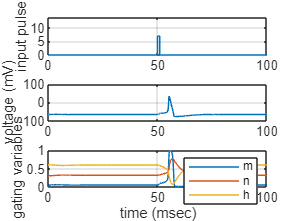

% Code based on Timothy Sauer - Numerical Analysis 2nd Edition
%
% Inputs: time inter 'interval',
%           ic 'initial voltage & 3 gating vars'
%           n 'steps'
%
% Outputs: y 'solution'
%
% Call one step method such as forward Euler or RK4
% Example Usage: hh([0, 100], [-65, 0, 0.3, 0.6], 2000)


function y = hh(inter, ic, n)
    global pa pb pulse
    inp = input('pulse start, end, muamps in [], e.g. [50 51 7]: ');
    pa = inp(1);
    pb = inp(2);
    pulse = inp(3);

    a = inter(1);
    b = inter(2);
    h = (b-a)/n;
    y(1, :) = ic;
    t(1) = a;
    for i = 1:n
        t(i+1) = t(i) + h;
        y(i+1, :) = rk4step(t(i), y(i, :), h);
    end

    subplot(3,1,1);
    plot([a pa pa pb pb b],[0 0 pulse pulse 0 0]);
    grid;axis([0 100 0 2*pulse])
    ylabel('input pulse')
    subplot(3,1,2);
    plot(t,y(:,1));grid;axis([0 100 -100 100])
    ylabel('voltage (mV)')
    subplot(3,1,3);
    plot(t,y(:,2),t,y(:,3),t,y(:,4));grid;axis([0 100 0 1])
    ylabel('gating variables')
    legend('m','n','h')
    xlabel('time (msec)')
end

function y = rk4step(t, w, h)
    % one step of the Runge-Kutta 4th order method
    s1 = ydot(t, w);
    s2 = ydot(t + h/2, w + h * s1/2);
    s3 = ydot(t + h/2, w + h * s2/2);
    s4 = ydot(t + h, w + h * s3);

    y = w + h * (s1 + 2*s2 + 2*s3 + s4) / 6;
end

function z = ydot(t, w)
    global pa pb pulse
    c = 1;
    g1 = 120;
    g2 = 36;
    g3 = 0.3;
    T = (pa + pb)/2;
    len = pb-pa;

    e0 = -65;
    e1 = 50;
    e2 = -77;
    e3 = -54.4;
    in = pulse * (1 - sign(abs(t-T) - len/2)) / 2;

    % square pulse input on interval [pa, pb] of pulse muamps
    v = w(1);
    m = w(2);
    n = w(3);
    h = w(4);
    z = zeros(1, 4);
    z(1) = (in-g1*m*m*m*h*(v-e1)-g2*n*n*n*n*(v-e2)-g3*(v-e3))/c;
    v=v-e0;
    z(2)=(1-m)*(2.5-0.1*v)/(exp(2.5-0.1*v)-1)-m*4*exp(-v/18);
    z(3)=(1-n)*(0.1-0.01*v)/(exp(1-0.1*v)-1)-n*0.125*exp(-v/80);
    z(4)=(1-h)*0.07*exp(-v/20)-h/(exp(3-0.1*v)+1);
end

hh([0, 100], [-65, 0, 0.3, 0.6], 2000);